# TP1 Analyse : Séries de Fourier et produits de convolution

*Le compte rendu est à rédiger directement dans ce document avec votre code que vous pourrez executer à partir de ce fichier section par section.*

*Il vous est demandé de montrer les résultats, de les analyser et les interpréter tout en répondant aux questions. Nous jugerons vos capacités à comprendre et interpréter mathématiquement les réalisations. *

***Assurez-vous toujours de la lisibilité des graphs : intitulés des axes, légende, échelle, etc.***

## ***1- Séries de Fourier***

### ***1.1 - Mise en place des signaux d'étude***

Le programme-ci dessous permet de générer, sur 2000 points, un signal sinusoidal d'amplitude 1, de fréquence 20Hz, échantillonné à 8kHz . Ecrivez le code qui permet de le visualiser en fonction du temps.

F0 = 20 ;   %fréquence du sinus en Hz
Fe = 8000;  %fréquence d'échantillonnage en Hz
N = 2000;   %nombre de points
t = (-N/2 : ((N/2)-1))/Fe;  %échelle de temps
sinus1 = sin(2*pi*F0*t);    %signal sinusoidal construit

%*******************************************************************************
% écrire ici le code qui trace le signal sinusoidal sinus1 en fonction du temps
%*******************************************************************************
figure



Fabriquez (sur la même échelle de temps que précédemment) un signal ***sinus3 ***de fréquence 60Hz et d'amplitude 1/3, et tracez-le sur le même graphique que ***sinus1***

%*******************************************************************************
% écrire ici le code qui fabrique sinus3 et le trace en fonction du temps
%*******************************************************************************

% sinus3 = ...



Fabriquez un 3ème signal en effectuant la somme des 2 signaux précédents (**sinus1** et **sinus3**) et observez le résultat sur un nouveau graphique.

%*******************************************************************************
% écrire ici le code qui fabrique sinus1+sinus3 et le trace en fonction du temps
%*******************************************************************************
figure

% sum1 =...

Fabriquez 2 signaux supplémentaires  ***sinus5***  (fréquence et amplitude à déterminer) ainsi que  la somme de **sinus1**, **sinus3** et **sinus5**, et tracez-les comme dans la figure 1.

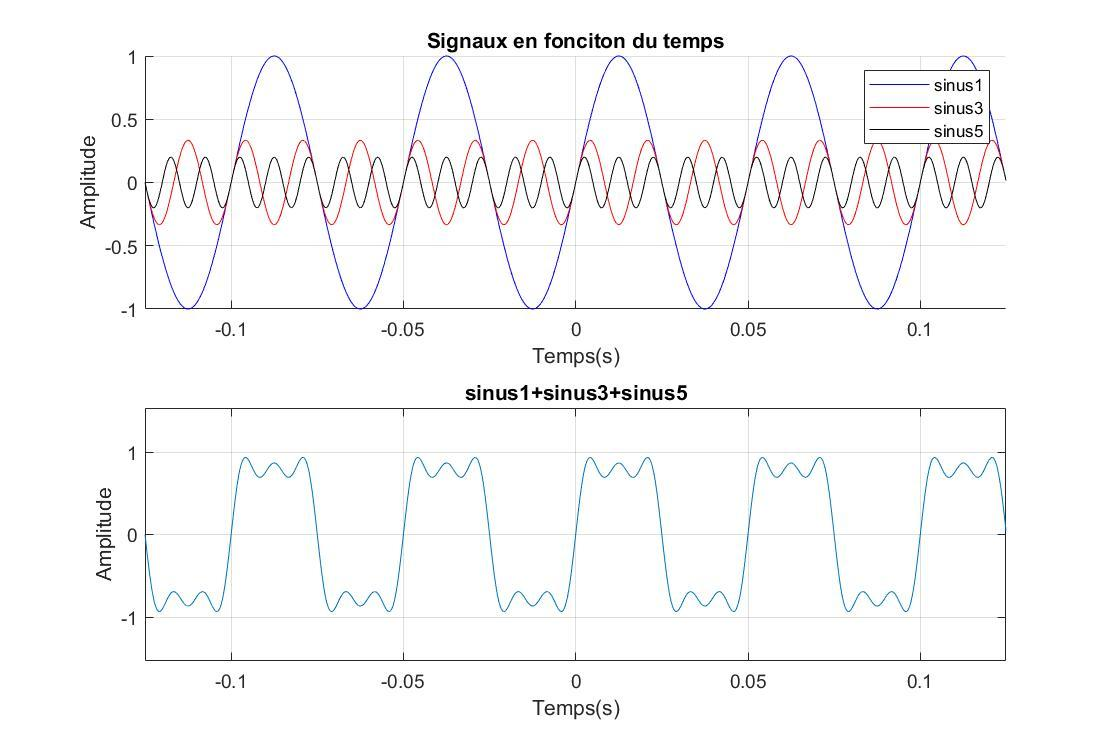

Figure 1 : Signaux sinusoidaux

%*******************************************************************************
% écrire ici le code qui fabrique sinus5 ainsi que la somme des trois signaux 
% et qui les trace en fonction du temps
%*******************************************************************************




Qu’essayons-nous de faire avec cette construction de signaux ?  Pourquoi ne considérons-nous que les sinus de rang impair ? **Justifiez.**

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

### ***1.2 - Critères de qualité***

On souhaite trouver le nombre d’harmoniques nécessaires pour arriver à tout instant à une différence de moins de 5% (entre 95% et 105%) par rapport au signal de référence.  

Il faut donc fabriquer un signal de forme carrée parfaite pour pouvoir lui comparer un signal recomposé et se demander si sa forme est satisfaisante, par exemple : 

*On rappelle que le rapport entre la valeur maximale d’un carré et celle de son fondamental est de* *pi/**4.*

On pourrait ensuite tracer deux autres signaux carrés qui définiront l’intervalle d’erreur tolérée et vérifier visuellement à partir de combien d’harmoniques le signal composé est totalement contenu dans cet intervalle. 

Implémentez, dans la section "**Les Fonctions**" à la fin de ce document, une fonction ***sommeHarmoniques*** qui retrourne la somme étant donné un nombre d'harmonique en entrée.

Ecrivez ci-desssous le code qui permet d'afficher l'intervalle de 5% (figure 2), qui appelle la fonction ***sommeHarmonique*** pour différentes valuers de n et trace la somme afin de trouver le nombre d'harmoniques nécessaires pour rentrer dans la marge de 5% d'erreur. 

%*******************************************************************************
% écrire ici le code qui appelle sommeHarmoniques pour différentes valeurs de n 
% fabrique les signaux carrés et les trace avec le signal somme
%*******************************************************************************

% executer le code avec différentes valeurs de n
n=10;   %chosir n

F0 = 20 ;   %fréquence du fondamental en Hz
Fe = 8000;  %fréquence d'échantillonnage en Hz
N = 2000;   %nombre de points
t = (-N/2 : ((N/2)-1))/Fe;  %échelle de temps

somme = sommeHarmoniques (n, F0,t) ;  % calculer la somme avec n harmonique

%-----------------------------------------------------------------------------
% fabriquer et tracer les 3 signaux carrés ainsi que le signal somme


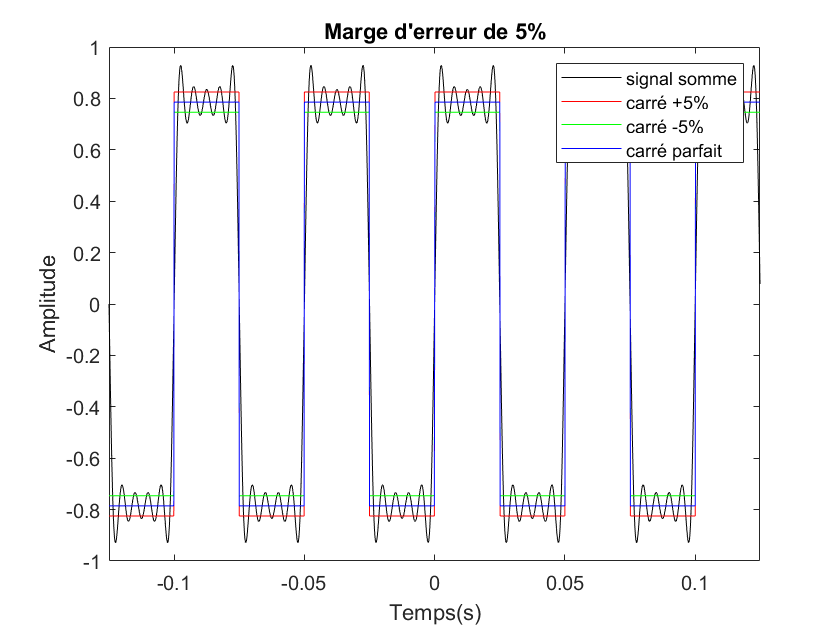

Figure 2 : Marge d'erreur de 5%

Combien d’harmoniques faut-il pour respecter la marge d’erreur de 5%?  ** Appelez un encadrant quand vous trouverez**

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

Les critères de qualité précédents vous semblent-ils pertinents ? 

Autrement dit, est-il pertinent (quelque soit l'application) de juger de la qualité d’un signal en se basant sur un dépassement en tout point ? **Justifiez.**  

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

On se propose d’évaluer un autre critère de qualité : l’erreur quadratique moyenne. 

Implémentez (dans la seciton fonciton) une fonction ***EQM*** qui retourne l'erreur quadratique moyenne pour un nombre d'harmoniques donné en entrée.

Utilisez la fonction EQM pour tracer l’erreur en fonction du nombre d’harmoniques.  

%*******************************************************************************
% écrire ici le code qui calcule les EQM pour différentes valeur de n
% et les trace en fonction de n
%*******************************************************************************

%-----------------------------------------------------------------------------
% définir un vecteur N qui contient toutes les valeurs de n que vous
% souhaitez utiliser
% N =...


%-----------------------------------------------------------------------------
% Ecrire une boucle qui calcule les erreurs pour chaque valeur du vecteur N
% et les stocke dans un vecteur Erreurs
% for ...
% Erreurs[i] = ...


%-----------------------------------------------------------------------------
% Tracer le vecteur Erreurs en fonciton du vecteur N



Commentez la forme de la courbe. Atteint-on zéro? 

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

Donner un avis scientifiquement argumenté sur ce nouveau critère de qualité  

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

## ***2- Convolution/ Déconvolution***

En de nombreuses occasions, on traite les signaux par transformation de Fourier. Cependant, quelques applications nécessitent l’emploi du produit de convolution. En général, les applications utilisent la déconvolution pour améliorer la résolution de mesures physiques en 1D (profilométrie), en 2D (optique, sismologie) etc. 

En microélectronique (ou dans d’autres domaines), on a souvent besoin de tester les matériaux fabriqués. On fabrique alors des marches-test et on mesure le résultat de fabrication à l’aide de profilomètres mécaniques :  

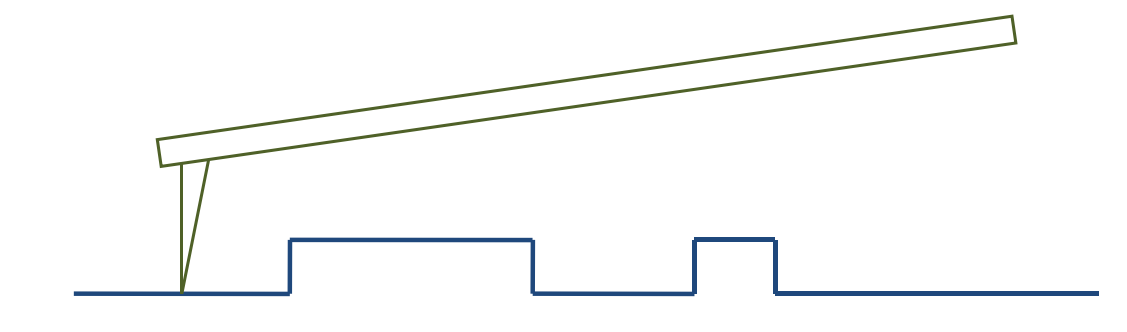

Figure 3 : Profilomètre

Le déplacement de la pointe permet de mesurer le profil des motifs. Les pointes les plus petites sont utilisées dans des profilomètres mécaniques particuliers appelés AFM (Atomic Force Microscope :microscope à force atomique)

Malheureusement, en général la pointe n’est pas infiniment fine (ni infiniment longue mais on supposera sa longueur suffisante) et le profil mesuré est d’autant plus affecté par le profil de la pointe que les marches ont des tailles proches de la taille de la pointe.

Les exercices suivants sont destinés à effectuer quelques manipulations avec le produit de convolution puis à appliquer la convolution sur un exemple réel.  

### 2.1- Convolution de deux signaux élémentaires

On propose de générer sur *N *= 1024 points un signal valant 0 jusqu’à la moitié de l’échantillon, puis exponentiel décroissant à partir de la moitié de l’échantillon avec une décroissance de 63% pour 1/10ème de la longueur de l’échantillon.

Le vecteur temps sera défini de manière à ce que t=0 soit situé au milieu du vecteur.

On souhaite également générer sur *N *= 1024 points un signal échelon unitaire échantillonné à une fréquence *f**e *= 8kHz. 

Le code ci-dessous permet de fabriquer ces deux signaux. Tracez-les sur un même graphique  

Fe = 8000;  %fréquence d'échantillonnage
Te = 1/Fe;  %période d'échantillonnage
N = 1024;   %nombre de points
t = (-N/2 : ((N/2)-1))/Fe;  %échelle de temps
echelon = (1+sign(t))/2;    %signal échelon
expo = echelon .* exp(-t/0.01) ; %signal exponentiel

%-----------------------------------------------------------------------------
% Tracer echelon et expo en fonction du temps sur un même graphique




Sur papier, convoluez (graphiquement) ces deux signaux. Quelle est la forme du signal résultant ? **Expliquez**

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

L’instruction Matlab *conv *permet de calculer la convolution de 2 signaux. Calculer la convolution des deux signaux echelon et expo fabriqués et tracez le résultat comme dans la figure 4

%*******************************************************************************
% écrire ici le code qui calcule expo*echelon et trace le résultat sur la
% même figure que précedement mais sur un subplot différent (figure 4)
%*******************************************************************************
c = conv(echelon,expo) %calcul de la convolution
%-----------------------------------------------------------------------------
% Tracer le vecteur c





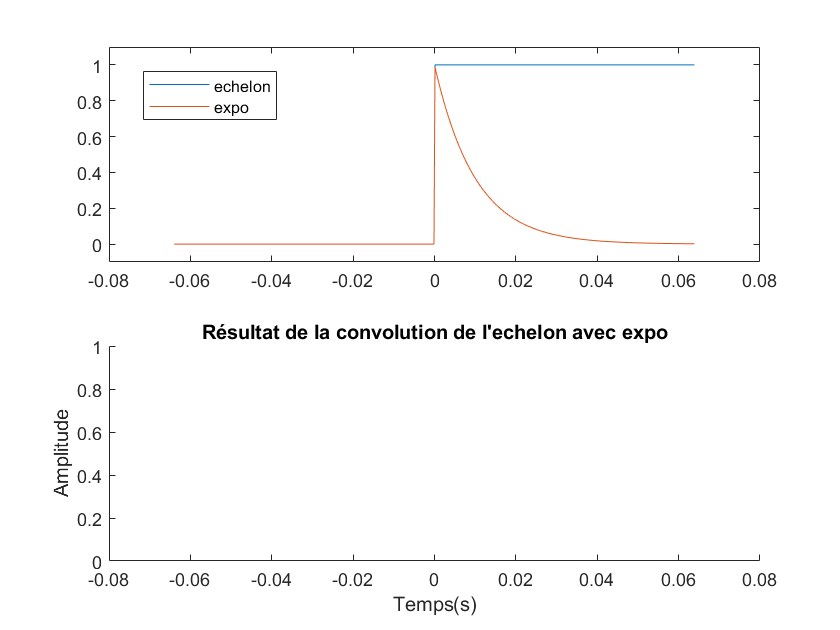

Figure 4: Convolution des signaux élémentaires

Le résultat calculé par Matlab correspond-il à celui que vous aviez calculé sur papier ? **Expliquez**

*Indice: Regardez la taille des vecteurs générés. Le vecteur résultat est il homogène aux vecteurs initiaux (et cohérent vis-à-vis du vecteur temps) ?  *

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

Comment faire pour que Matlab donne un résultat conforme au vôtre?

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

Donnez un exemple d’application qui peut être représentée par la convolution réalisée. 

*Indice : que vous rappelle la forme du signal exponentiel ? Que représente la convolution par ce signal*

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

### 2.1- Convolution d'une pointe avec des profils

Fabriquez un vecteur impulsion de taille 7 : 

Fabriquez un deuxième vecteur **marche** sur 1024 points avec une largeur de marche d’amplitude 1 sur 400 points (figure 5). 

Convoluez ces deux signaux.

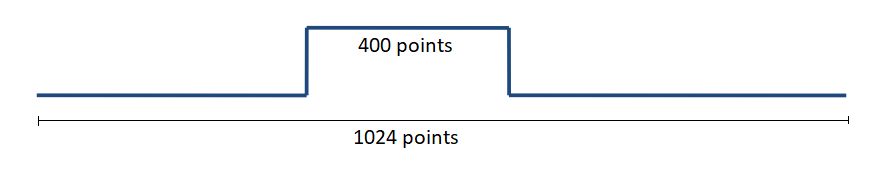

Figure 5: Marche

%*******************************************************************************
% écrire ici le code qui fabrique imp et la marche de la figure 5, les
% trace, les convolue et trace le résultat
%******************************************************************************




Le produit de convolution de l’impulsion avec la marche est-il une surprise pour vous ? Expliquez pourquoi.  

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

Fabriquez un vecteur **pointe_parfaite** sur 1024 points. La pointe aura une largeur de 40 points et un maximum égal à 1  (figure 6)

  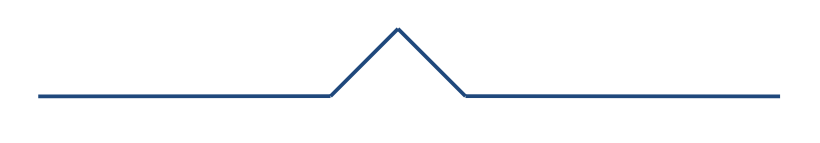

Figure 6: Pointe parfaite

On pourrait la fabriquer en appliquant un produit de convolution entre deux vecteur à déterminer.  Expliquez le choix de ces vecteurs, de leurs largeurs et de leurs amplitudes.

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

Calculez le produit de convolution de la **pointe_parfaite** avec la  **marche**  de la figure 5

%*******************************************************************************
% écrire ici le code qui fabrique la pointe parfaite,calucle le produit
% de convolution avec le signal "marche", et trace les vecteurs impliqués
%******************************************************************************





Commentez le résultat de la convolution  

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

Deux défauts sont habituellement constatés sur les pointes : le bout est cassé / le bout est arrondi. Fabriquez, par convolution, 2 vecteurs plausibles simulant des défauts de la pointe (ex: figure 7)

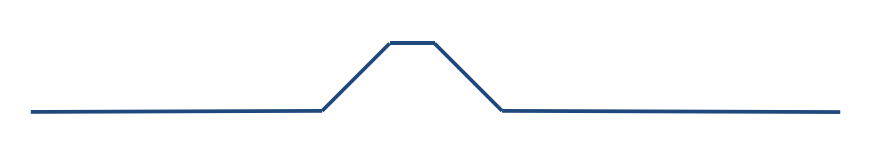

Figure 7: Pointe cassée

%*******************************************************************************
% écrire ici le code qui fabrique une pointe cassé et une pointe arrondie
%******************************************************************************





Expliquez le choix des signaux utilisés pour la fabrication  

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

Fabriquez un vecteur "marches" de longueur 1024 points mais comportant des petits motifs  (ex: figure 8)

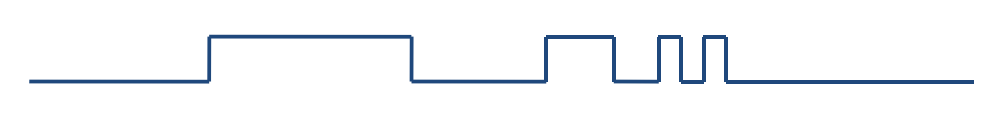

Figure 8: Marches

Effectuez la convolution des pointes avec le profil de marches nouvellement créé, pour obtenir des résultats de mesure :

    - Marches mesurées par la pointe parfaite

    - Marches mesurées par la pointe cassée

    - Marches mesurées par la pointe arrondie  

%*******************************************************************************
% écrire ici le code qui fabrique le vecteurs marches et qui le convolue
% avec les trois pointes (parfaite, cassée, arrondie)
%******************************************************************************






Commentez les résultats de convolution  

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

### 2.2- Reconstitution des profils par déconvolution

Reconstituez, par déconvolution, les marches originales si l’opérateur suppose la pointe encore en bon état.  

%*******************************************************************************
% écrire ici le code qui reconstitue le profil en déconvoluant avec la pointe 
% parfaite
%******************************************************************************





Concluez sur l’effet des défauts des pointes de mesure.  

*************************************************************************************************************** 

***VOTRE REPONSE ICI***

## Les Fonctions

function somme = sommeHarmoniques (n, F0, t)
%*******************************************************************************
% écrire ici le code qui retourne la somme de n harmoniques sinus de rang
% impaire
%******************************************************************************



end

function erreur = EQM(n)
%*******************************************************************************
% écrire ici le code qui fabrique un signal avec n harmoniques sinus de rang
% impaire, calcule et retourne l'erreur quadratique moyenne entre le signal 
% carré de référence et le signal composé
%*******************************************************************************

end